**Lab 3**

**Problem 1**

Set up the problem by creating a Gaussian with 100k points centered around 12 with a variance of 0.4.

pd = makedist('Normal',"mu",12,"sigma",0.4);
backV = random(pd,[1 100000]);

Create a vector of outliers, and concatenate that vector with the vector of Gaussian-distributed points.

outliers = [10. 10.3 2.1 0. 0. 15.6 22.3 12.7];
backV = [backV,outliers];

*A) Idenfity bad data and throw it out*

*1) Create appropriate plots*

I love how clear our directions are. It is actually really cool to artificially make labs harder by throwing in lack of direction, while expecting that the labs explain the process with high attention to detail.

I will plot the combined vector of points on regular and log axes.

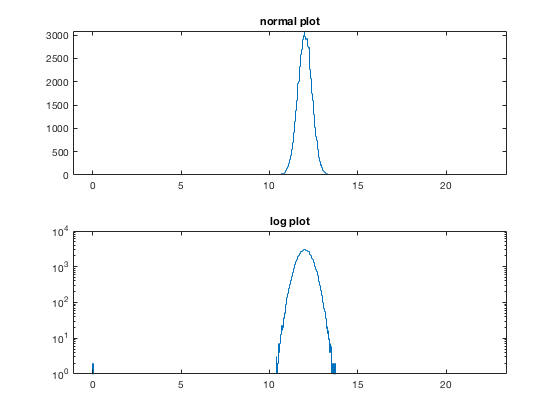

figure;
subplot(2,1,1);
histogram(backV,'DisplayStyle','stairs','LineStyle','-');
% histogram(backV);
title('normal plot');
subplot(2,1,2);
histogram(backV,'DisplayStyle','stairs','LineStyle','-');
% histogram(backV);
set(gca,'YScale','log');
title('log plot');

*2) Write the statistical question*

I have a group of normally distributed points about a value, 12, with a variance of 0.4. I aim to throw out all the "outlying" points which are defined as points 0.7 away from the mean in either direction (since this was not specified in the lab, I will exercise my right to choose — that is the smallest outlier given). I want to find out how many of the discarded points will be points associated with the original outliers vector, and how many points will be at the threshold due to fluctuations in the distribution.

threshold = 0.6999;%slightly less than 0.7 to avoid rounding

Once again, this threshold was chosen to be such that it would capture all of the outliers, and since the smallest difference from mean is 0.7, that is the threshold value.

*3) Convert the question to math/code*

With how I chose to filter the outliers, there's not really math here, as much as code.

clear thrownOut
r = 1;
for i = 1:100008
    if abs(backV(i) - 12) >= threshold
        thrownOut(r) = backV(i);
        r = r+1;
    end
end

The number of points thrown out is much larger than desired, which makes sense because the threshold chosen was small (in order tocapture all of the given outliers).

*4) Create a truth table.*

By my choice of the threshold, I am guaranteed to have caught all of the "forced outliers" from the original outliers vector. However, because of that, I have also thrown out quite a few points that were created by the normal distribution.

TruePositive = length(backV) - length(thrownOut);
[~,falseN] = ismember(outliers,thrownOut);
thrownOut(falseN)

ans =    10.0000   10.3000    2.1000         0         0   15.6000   22.3000   12.7000


falseNa = nonzeros(falseN);
FalseNegative = length(falseNa);
TrueNegative = length(thrownOut) - length(falseN);
FalsePositive = 0;%forced by my choice of threshold

*B) How does the number of omissions, where you threw out good data, depend on the statistical threshold you chose and is it a predictable quantity?*

The "stricter" the threshold that I choose, the less good data points I will throw out. To some degree, it can be argued that this is a semi-predictable quantity, because although I cannot say how many points I will throw out if I set the threshold to be low (meaning the variance is not far from the mean), I can confidently say that there will be VERY few points created by the distribution (good points) that I throw out if I set the threshold high (even values like 1.7 will essentially guarantee that no good points are thrown out). That being said, by adjusting my threshold to something stricter, I will also miss some of the points that were forced to be "bad points," by the nature of the fact that in this problem I set the threshold to be the minimum needed to catch all forced "bad points."

*C) Are there mistakes of commission (bad data getting in)? If yes, are they avoidable and how do they depend on your statistical threshold?*

Based on my choice of threshold, there are no mistakes of commission. This can be shown by comparing length of two vectors I created in section A part 4 — falseNa and the outliers vector. 

falseNa contains all non-zero entries of the falseN vector, which in turn is a vector that gives indices of each value of the vector outliers if they are contained within the vector thrownOut, and 0 if they are not. Therefore, since falseNa contains all non-zero entries of falseN, comparing lengths of falseNa and outliers will give how many of the outliers are contained in thrownOut.

delta = abs(length(outliers) - length(falseNa))

delta = 0

The delta is shown to be zero, so all of the points initially forced to be "bad points" were thrown out, as is expected by my choice of threshold. (There is a caveat that falseNa only found the lowest index of the value contained in thrownOut, and we have two 0 values, so one of the indices is repeated. However, by printing out values of thrownOut at indices of falseNa and comparing those values to values of vector outliers, we can guarantee that all points are accounted for).

**Problem 2**

I want to recreate the 2d matrix that contains the distribution (don't want to plot it, however).

pd2 = makedist('Normal',"mu",0,"sigma",1);
xDist = sort(random(pd2,[1 100000]));%arcsec in x
yDist = sort(random(pd2,[1 100000]));%arcsec in y
xDistUns = random(pd2,[1 100000]);
yDistUns = random(pd2,[1 100000]);

*1) What is the question in words?*

I am interested in finding the distance that would constitute a 5 sigma detection. Given the 2D Gaussian distribution, I can create a new 1D distribution that is "circular," in that it takes as input R = sqrt(x^2 + y^2), where x and y are the two directions of the Gaussian distribution. What is the threshold on this new distribution that is associated with 5 sigma probability?

*2) What is the question in math?*

I aim to create this R-dependent distribution, and see how that looks first. I also want to check whether sorting arrays before averaging will have an effect.

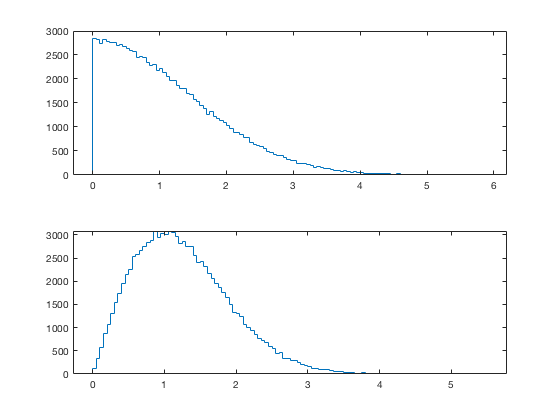

clear i;
rDist = zeros([1 100000]);
rDistUns = zeros([1 100000]);
for i = 1:100000
    rDist(i) = (xDist(i)^2 + yDist(i)^2)^0.5;
    rDistUns(i) = (xDistUns(i)^2 + yDistUns(i)^2)^0.5;
end
rDist = sort(rDist);
figure;
subplot(2,1,1);
histogram(rDist,'DisplayStyle',"stairs",'LineStyle','-','LineWidth',0.2);
subplot(2,1,2);
histogram(rDistUns,'DisplayStyle',"stairs",'LineStyle','-','LineWidth',0.2);

The top distribution looks weird, maybe like a stretched-out half-Gaussian? The 2nd one looks quite a bit like a Rayleigh distribution however, which fits with the parameters we're using in the problem. I want to create a Rayleigh distribution with 100000 points and compare it to the result above.

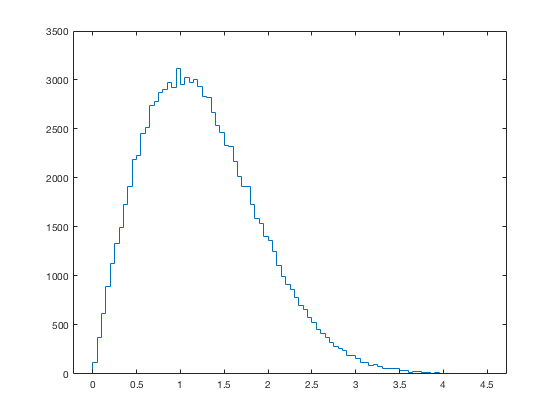

testRay = makedist('Rayleigh');
rayRand = random(testRay,[1 100000]);
figure;
histogram(rayRand,'DisplayStyle',"stairs",'LineStyle','-','LineWidth',0.2);

The two look extremely similar, meaning that a Rayleigh distribution is indeed the way to map the original 2D distribution as a 1D distribution. This also fits, since the Rayleigh distribution is made from two independent parameters, such that Z = Sqrt(X^2 + Y^2), where X and Y are parameters of normally distributed independent parameters, and Z the input of the Rayleigh. This is identical to our setup.

This means that we can re-create and solve the problem using an appropriate Rayleigh distribution. An important feature to note is that both of the Gaussian distributions had a mean of 0 and sigma of 1, and the resulting Rayleigh was "centered" at around 1. The simulated Rayleigh distribution I made to check had the same pattern, so I think it would be accurate to re-create the problem with a new Rayleigh centered at 1 (testRay should suffice).

prob5sigma = 1/(3.6e6);
threshold2 = icdf(testRay,1-prob5sigma)

threshold2 = 5.4948

The found threshold is 5.4948 R, where R = Sqrt(X^2 + Y^2). So the threshold value is the  radius at which the asteroid would have to pass for a 5-sigma detection (that or higher).

**Problem 3**

*1) What is the question in words?*

A moon-sized patch on the sky has a rate of about 1 cosmic ray per minute. This means that for the given duration of the observation, we would expect to see (1 observation per minute) * (60 minutes per hour) * (8 hours of observation per day) * (15 days of observation) = 7200 observations. This is the expected result if no cosmic rays are being absorbed. The observed signal is 6800, which is attributed to absorption by the moon passing through our angle of observation. What is the probability that the observed signal is not the result of our background, thus being a detection of the moon's shadow?

*2) Translate the question to math, describing both the expected background pdf() and the integral you need to do.*

First, I need to create a distribution of the background signal. The cosmic ray arrivals are random in time, and have an expected value of 1 ray per minute. These characteristics hint that the background should be a Poisson distribution (as the number of events is low, and the observation span is quite long).

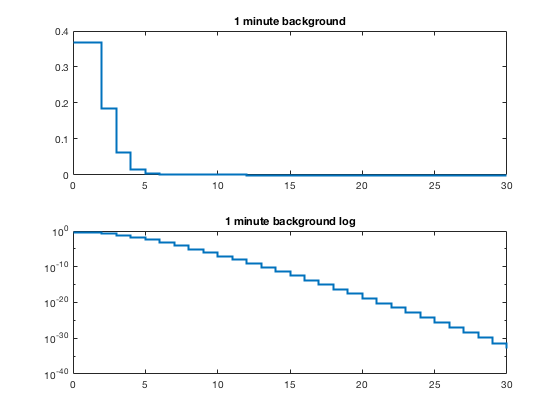

avgRays = 1;
background = makedist("Poisson","lambda",avgRays);
x = 0:30;
backgroundPDF = pdf(background,x);
figure;
subplot(2,1,1);
stairs(x,backgroundPDF,'LineStyle',"-","LineWidth",2);
name = '1 minute background';
title(name);
subplot(2,1,2);
stairs(x,backgroundPDF,'LineStyle',"-","LineWidth",2);
set(gca,'YScale','log');
title(strcat(name,' log'));

Convert the 1-minute background to expected background over the whole measurement period.

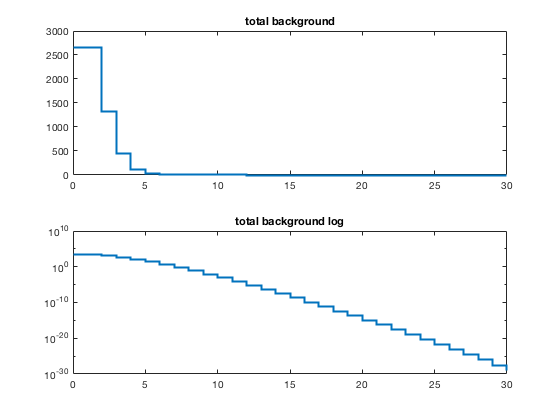

numTotal = 7200;
backgroundTotal = backgroundPDF*numTotal;
figure;
subplot(2,1,1);
stairs(x,backgroundTotal,'LineStyle',"-","LineWidth",2);
name = 'total background';
title(name);
subplot(2,1,2);
stairs(x,backgroundTotal,'LineStyle',"-","LineWidth",2);
set(gca,'YScale','log');
title(strcat(name,' log'));

Now we need to cleverly do the integral. Because of how distribution objects behave in matlab, I do not think there is a simple way to integrate a pdf of a distribution object — we need to integrate the distribution object itself. Distribution objects, however, cannot be scaled in the same way that I've scaled the background distribution. This means that we need to change in integration bounds in order to pretend as if the background distribution got scaled. 

Another thing to note is because the signal is below the distribution, we should be integrating differently than done in previous labs. Cdf() gives the probability that the distribution is less than or equal to the value given, which is exactly what we aim to integrate here.

signal = 6800;
prob = cdf(background,signal/numTotal)

prob = 0.3679

An issue I am noticing is the above method is identical to finding that the rate of cosmic ray observation is decreased flatly over each interval. The expected outcome, however, is that for parts of the night the signal will be decreased due to us observing the moon, thus we may expect to see no cosmic rays for many minutes, while for other times, the background would behave "as normal."

Another one of the issues I am currently noting is that the observed signal is not necessarily a production of moon-detection — other objects could have absorbed the rays as well, or diverted their path in some way. This could also detract from our detection of the moon's shadow, reducing the confidence on the result.

*3) Convert to sigma.*

We take the probability found in part 2, and see what sigma this probability corresponds to on a normal distribution.

sigma = icdf('Normal',1-prob,0,1)

sigma = 0.3375

The observed sigma is 0.3375. This is extremely low, and suggests that we have a very low confidence value that the observed effect is due to the passing of the moon, rather than fluctuations in our background distribution. This confidence is further suppressed by issues that I've outlined at the end of part 2 (not being sure if the moon is the sole reason the signal is decreased, as well as the integration method not accounting for the fact that the moon would only affect distinct parts of the observation cycle).